% Load Users

udata = load('u.data');                                                             % Carrega o ficheiro dos dados dos filmes
u = udata(1:end,1:2); clear udata;                                                  % Fica apenas com as duas primeiras colunas
dic = readcell('u_item.txt');                                                       % Load das categorias dos filmes

users = unique(u(:,1));                                                             % Extrai os IDs dos utilizadores
Nu= length(users);                                                                  % Número de utilizadores
Bestk = zeros(1,105/5);
BestK = zeros(1,105/5);
Timek = zeros(1,105/5);
TimeK = zeros(1,105/5);

Set= cell(Nu,1);                       
for n = 1:Nu                                                                     
    ind = find(u(:,1) == users(n));
    Set{n} = [Set{n} u(ind,2)];
end

threshold = 0.99;
for l = 1:21
    kapas = [100:5:200];
    K = kapas(l);
    J = zeros(Nu);                                                                      
    MinHashTable = inf(Nu,K);
    
    tic;
    
    for i = 1:Nu
        conjunto = Set{i};
        for j = 1:length(conjunto)
            chave = char(conjunto(j));
            h = zeros(1,K);
            for kk= 1:K
                chave = [chave num2str(kk)];
                h(kk) = DJB31MA(chave, 127);
            end
            MinHashTable(i,:) = min([MinHashTable(i,:);h]);
        end
    end
    
    Timek(l) = toc;
    
    for n1= 1:Nu
        for n2= n1+1:Nu
            J1(n1,n2)= sum(MinHashTable(n1,:) ~= MinHashTable(n2,:))/K;
            if J1(n1,n2) <= threshold
                Bestk(l) = Bestk(l) + 1;
            end
        end
    end
       
    ntitles = length(dic);                                                              
    s = 2;                                                                             
    k = K;                                                                              
    seed = randi(10000,k,1);                                                            
    
    tic;
    
    for n = 1:length(dic)                                                               
        title = char(lower(regexprep(dic(n,1),'[,''.() ]',"")));                        
        hash = zeros(s,k);                               
        for i = 1:length(title)-s                                                                     
            for h = 1:k                                                                 
                hash(i,h) = mod(DJB31MA(title(i:i+s), seed(h)),199999);                            
            end
        end
        for i = 1:k                                                                  
            hCodes(i,n) = min(hash(:,i));                                                 
        end
    end
    
    TimeK(l) = toc;
    
    for n1 = 1:length(hCodes(:,1))
        for n2 = n1+1:length(hCodes(:,1))
            J2(n1,n2)= sum(hCodes(n1,:) ~= hCodes(n2,:))/K;
            if J2(n1,n2) <= threshold
                BestK(l) = BestK(l) + 1;
            end
        end
    end    
end
save("BestHashFuncNum","BestK","TimeK","Bestk","Timek");


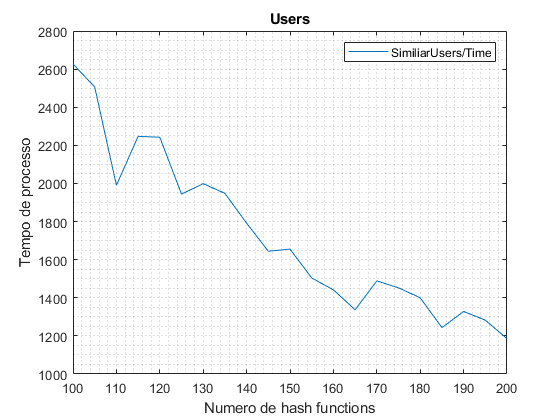

load("BestHashFuncNum.mat")
clear title;

% Para users
plot(kapas,Bestk./Timek);
legend("SimiliarUsers/Time");
grid("minor");
title("Users");
xlabel("Numero de hash functions");
ylabel("Tempo de processo");

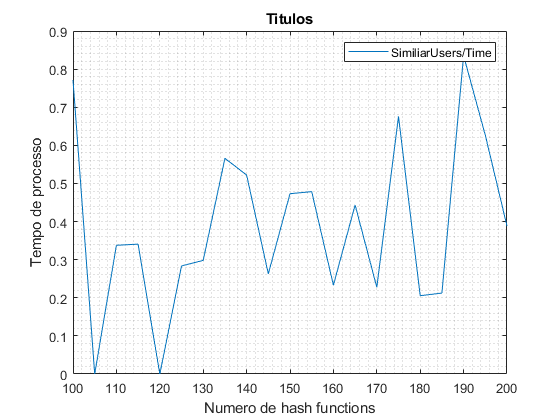


% Para shingles
plot(kapas,(BestK./TimeK));
legend("SimiliarUsers/Time");
grid("minor");
title("Titulos");
xlabel("Numero de hash functions");
ylabel("Tempo de processo");